## Example #1

### 2D point

n = [1 1]';
P = n;
V = [2 2]';
S = orthogonal_reflection(V, P, n) % expected : S = [0; 0]

S =      0
     0


##  Example #2

### Array of 2D points

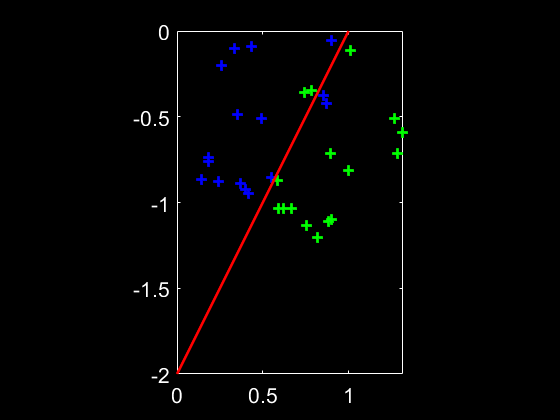

n = [2 -1]';
P = [1 0]';
nb_pts = 16;
V = rand(2,nb_pts) - cat(1,zeros(1,nb_pts),ones(1,nb_pts));
S = orthogonal_reflection(V,P,n);

figure;
plot(V(1,:),V(2,:),'b+','MarkerSize',8,'Linewidth',2), hold on;
plot(S(1,:),S(2,:),'g+','MarkerSize',8,'Linewidth',2), hold on;
line([0 1],[-2 0],'Color',[1 0 0],'Linewidth',2), hold on;
axis equal, axis tight;
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1],'FontSize',16);

##  Example #3

### Random array of 3D points

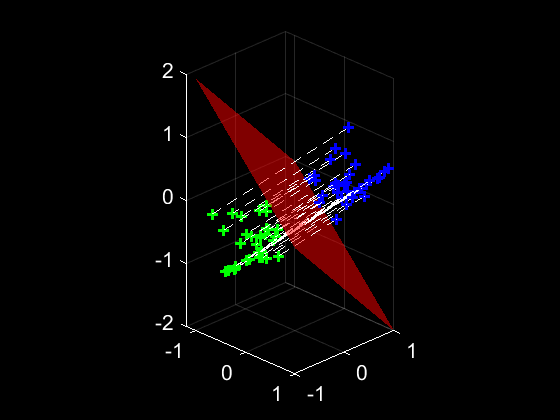

n = [1 1 1]';
P = [0 0 0]';
nb_pts = 32;
V = rand(3,nb_pts);
S = orthogonal_reflection(V,P,n);

figure;
[X,Y] = meshgrid(-1:0.1:1,1:-0.1:-1);
Z = -X-Y;
surf(X,Y,Z), shading interp, hold on;

plot3(V(1,:),V(2,:),V(3,:),'b+','MarkerSize',8,'Linewidth',2), hold on;
plot3(S(1,:),S(2,:),S(3,:),'g+','MarkerSize',8,'Linewidth',2), hold on;
cellfun(@(c1,c2) line([c1(1) c2(1)],[c1(2) c2(2)],[c1(3) c2(3)],'LineStyle','--','LineWidth',0.5,'Color',[1 1 1]),num2cell(V,1),num2cell(S,1),'un',0);

colormap([1 0 0]);
alpha(0.5);
axis equal, axis tight;
view(45,26);
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1],'FontSize',16);

##  Example #4

### Another array of 3D points

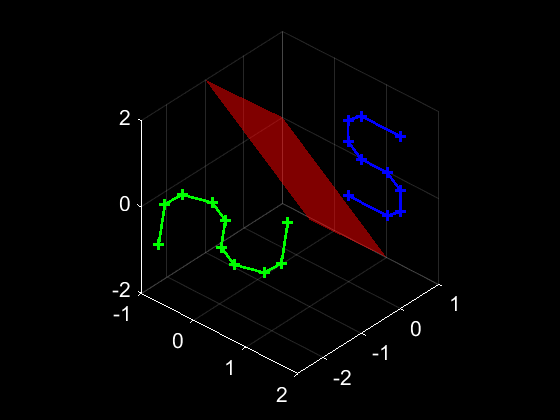

n = [1 1 1]';
P = [0 0 0]';
V = cat(1,[2 1.25 1 1 1.25 1.75 2 2 1.75 1],zeros(1,10),[2 2 1.75 1.25 1 1 0.75 0.25 0 0]);
S = orthogonal_reflection(V,P,n);

figure;
[X,Y] = meshgrid(-1:0.1:1,1:-0.1:-1);
Z = -X-Y;
surf(X,Y,Z), shading interp, hold on;

plot3(V(1,:),V(2,:),V(3,:),'b+','MarkerSize',8,'Linewidth',2), hold on;
line(V(1,:),V(2,:),V(3,:),'Color',[0 0 1],'Linewidth',2), hold on;
plot3(S(1,:),S(2,:),S(3,:),'g+','MarkerSize',8,'Linewidth',2), hold on;
line(S(1,:),S(2,:),S(3,:),'Color',[0 1 0],'Linewidth',2), hold on;

colormap([1 0 0]);
alpha(0.5);
axis square, axis tight;
view(42,35);
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'ZColor',[1 1 1],'FontSize',16);